clear;

list = dir('*.csv');
numFiles = length(list);
Mx = cell(numFiles,2);    
Fx = cell(numFiles,2);  
G = cell(numFiles,2);
TRUE = 0;
REVERSE = 0;
FALSE = 0;
%実験ごとのIndexの違い
EnvDelayIndex = 6;
AmpDifIndex = 5;
vibType = 0; % Vibration type

%データ格納セルの1列目に行の名前付け
    Mx{1,1} = "ImportData";
    for k = 0 : 6
          Mx{k+2,1} = k;
    end

%Indexごとの行列の抜き出し
    for i = 2:numFiles+1
%       [row, colmun] = size(list(i))
      Mx{1,i}= csvread(list(i-1).name,1,0);%csvファイルの2行目から読み込み（数値のみしか読めない）   
      % 0から取り込んだindex列の最大値まで
      for indexNum = 0:max(Mx{1,i}(:,2)) 
          pickIndex = find(Mx{1,i}(:,2) == indexNum); %IndexNum(0~5,6)がある行番号を抜き出し 
           
          for k = 1:length(pickIndex)
            pick = pickIndex(k,1); %元データから取り出したい行番号をpickに代入する(1回ごとに更新される）
            Mx{indexNum + 2, i}(k,:) = Mx{1,i}(pick,:);%元データのpick行目をまとめ用セル行列に代入
          end          
      end      
    end

xlabelName = "Amplitude Ration (Strong : Weak)"

xlabelName = "Amplitude Ration (Strong : Weak)"

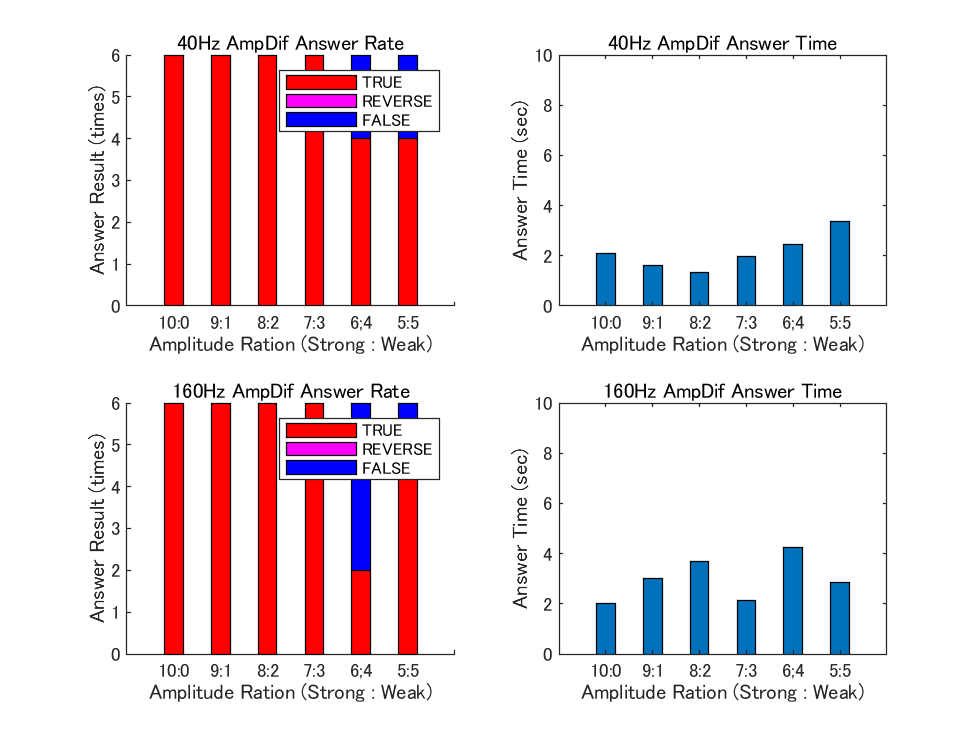


    %グラフ化用にデータを整理
    for i = 1 : numFiles  % ここでのiはcsvファイルの数
        
        for indexNum = 0: max(Mx{1,i +1}(:,2)) %Index(0-5,6)ごとの処理
            IndexArray = Mx{indexNum + 2, i + 1}; %各回の行列
            IndexMax = max(Mx{1,i +1}(:,2));
            GraphCell{1,i}(indexNum + 1, 1) = indexNum; %indexNumを挿入
            GraphCell{1,i}(indexNum + 1, 2) = mean(Mx{indexNum +2, i +1}(:,5)); %回答時間の平均値を挿入
%             switch Mx{2,i +1}(:,1)
%                 case 0
%                     vibType = 0;
%                 case 1
%                     vibType = 1;
%                 case 2
%                     vibType = 2;
%                 case 3
%                     vibType = 3; 
%             end
            

%%%%%%%%%%%%%%%            
            for k = 1:length(Mx{2,i +1}(:,2))%対象の試行回数分,1行ずつの処理
            
            %実験の種類によって成否の処理方法を変更
            if IndexMax == EnvDelayIndex
               
                switch indexNum
                    %Indexが0,(max-1)のとき、答えが2（同時）でTrue、それ以外はFalse
                    case {0, IndexMax}
                        if IndexArray(k,4) == 2
                            TRUE = TRUE + 1;
                        else
                            FALSE = FALSE + 1;
                        end
                      %  :max(Mx{1,i +1}(:,2)) - 1
                    case {1,2,3,4,5}
                        if IndexArray(k,4) == 2                            
                               FALSE = FALSE + 1;
                        elseif IndexArray(k,3) == IndexArray(k,4)
                                 TRUE = TRUE +1; 
                           else
                                REVERSE = REVERSE + 1;
                        end
                end % switch
              
            elseif IndexMax == AmpDifIndex
                
                switch indexNum
                    %Indexが0,(max-1)のとき、答えが2（同時）でTrue、それ以外はFalse
                    case {IndexMax}
                        if IndexArray(k,4) == 2
                            TRUE = TRUE + 1;
                        else
                            FALSE = FALSE + 1;
                        end
                      %  :max(Mx{1,i +1}(:,2)) - 1
                    case {0,1,2,3,4}
                        if IndexArray(k,4) == 2                            
                               FALSE = FALSE + 1;
                        elseif IndexArray(k,3) == IndexArray(k,4)
                                 TRUE = TRUE +1; 
                           else
                                REVERSE = REVERSE + 1;
                        end
                end % switch
               
            end %elseif IndexMax == AmpDifIndex
            

            GraphCell{1,i}(indexNum + 1, 3) = TRUE;
            GraphCell{1,i}(indexNum + 1, 4) = REVERSE;
            GraphCell{1,i}(indexNum + 1, 5) = FALSE;
            
            end

          %次のIndexに移る前に初期化              
            TRUE = 0;
            REVERSE = 0;
            FALSE = 0;      
      
%%%%%%%%%%%%% for k        
        end
        
        vibType = IndexArray(1,1);
        GraphArray = GraphCell{1,i};
        
%%% グラフのタイトルおよび軸の命名  
%%EnvDelayの場合
    if IndexMax == EnvDelayIndex
    xlabelName = "EnvelopeDelay(times period)"    
    
        switch vibType
            case 0
                graphtitle = "1-40Hz EnvDelay";
            case 1
                graphtitle = "1-160Hz EnvDelay";
            case 2
                graphtitle = "3-40Hz EnvDelay";
            case 3
                graphtitle = "3-160Hz EnvDelay";
        end

%%% 軸ラベル
%                 x1 = 0.167;
%                 x2 = 0.125;
%                 x3 = 0.083;
%                 x4 = 0.042;
%                 x5 = 0.021;
%                 x6 = 0.010;
%                 x7 = 0.0;
           Xtickslabel = ["1/2","3/8","1/4","1/8","1/16","1/32","0"];
%                 x1 = "1/2";
%                 x2 = "3/8";
%                 x3 = "1/4";
%                 x4 = "1/8";
%                 x5 = "1/16";
%                 x6 = "1/32";
%                 x7 = 0;

%%AmpDifの場合           
    elseif IndexMax == AmpDifIndex
    xlabelName = "Amplitude Ration (Strong : Weak)"    
        
        switch vibType
            case 0
                graphtitle = "40Hz AmpDif";
            case 1
                graphtitle = "160Hz AmpDif";
        end
                   Xtickslabel = ["10:0","9:1","8:2","7:3","6;4","5:5"];
% 
%                 x1 = "10:0";
%                 x2 = "9:1";
%                 x3 = "8:2";
%                 x4 = "7:3";
%                 x5 = "6;4";
%                 x6 = "5:5";      
    end                
%%%                
                x = GraphArray(:,1);
                Time = GraphArray(:,2);
                T = GraphArray(:,3);
                R = GraphArray(:,4);
                F = GraphArray(:,5);
                
                subplot(numFiles,2,2*(vibType+1)-1)
                 hold on
                % yyaxis right
                
                b = bar(x,[T R F],0.4,'stacked','FaceColor','flat');
                b(1).FaceColor = 'r';
                b(2).FaceColor = 'm';
                b(3).FaceColor = 'b';
                xlabel(xlabelName)
                legend("TRUE", "REVERSE","FALSE");
                ylabel("Answer Result (times)")
                ylim([0 6])
                title(graphtitle + " Answer Rate");
                xticks(0:1:6)
                xticklabels(Xtickslabel)
                     
                hold off
                %subplot
                subplot(numFiles,2,2*(vibType+1));
                
                bar(x,Time,0.4)
                xlabel(xlabelName)
                ylabel("Answer Time (sec)");
                ylim([0 10])
                title(graphtitle + " Answer Time");
                xticks(0:1:6)
                xticklabels(Xtickslabel)
                % xlim([0 6])
                % legend("AnserTime");
                
    end

% delete(gca)
%     
% GraphArray = GraphCell{1,1};
% GraphArray2 = GraphCell{1,2};
% 
% x = GraphArray(:,1);
% Time = GraphArray(:,2);
% T = GraphArray(:,3);
% R = GraphArray(:,4);
% F = GraphArray(:,5);
% 
% subplot(2,1,1);
%  hold on
% % yyaxis right
% 
% b = bar(x,[T R F],0.4,'stacked','FaceColor','flat')
% b(1).FaceColor = 'r'
% b(2).FaceColor = 'm'
% b(3).FaceColor = 'b'
% % stem(GraphArray1(:,1), GraphArray1(:,3),'filled','Color','r','LineStyle','none');
% % stem(GraphArray1(:,1), GraphArray1(:,4),'filled','Color','m','LineStyle','none');
% % stem(GraphArray1(:,1), GraphArray1(:,5),'filled','Color','b','LineStyle','none');
% xlabel("EnvelopeDelay")
% legend("TRUE", "REVERSE","FALSE");
% ylabel("Answer Result (times)")
% ylim([0 24])
% 
% hold off
% % yyaxis left
% 
% subplot(2,1,2);
% bar(x,Time,0.4)
% ylabel("Answer Time (sec)");
% ylim([0 10])
% % xlim([0 6])
% % legend("AnserTime");
% 
% hold off

% %まずは指定したIndeが何行目にあるかを見つける
% pickIndex = find(Data(:,2) == 0); %取り込んだデータのIndexが0である行の検索
% 
% %
%     for i = 1:length(pickIndex)
%         Pickup = pickIndex(i,1); %元データから取り出したい行番号をkに代入する
%         Mx{(i,:) = Data(k,:);%元データのk行目をまとめ用行列に代入
%     end
